clear; close all; clc; % initializes environment

# 多変量データと多変量解析

## 本章の目的

本章では，「多変量データ」と「多変量解析」を紹介し，多変量解析の意義をお伝えします．まず，多変量データとはどんなものかを具体例で示します．つぎに，多変量解析といわれる手法をいくつか紹介します．最後に，多変量解析の意義について概説します．

## データの準備

まずは説明に用いるデータセットを読み込んでおきます．説明には「米国３２９都市の生活満足度」データセットを用います．

load cities.mat; % loads dataset

## 多変量データ

ここでは，表形式にまとめられたデータratingsを用いて多変量データについて概説します．最初にratingsのデータ形式を確認したあと，多変量データおよび一変量データ，二変量データを紹介します．

### データの形式

ratingsがどのような形式になっているか見てみましょう．

ratings % displays the contents of the "ratings," again.

ratingsは米国３２９都市における生活満足度の評価値を表します．各都市の生活満足度は９つのカテゴリーで評価されています．各行はひとつの都市に対応し，各列はそれぞれの評価カテゴリーに対応します．一般に，データは何らかの値（数値や文字列など）の集まりです．データを解析する際には解析しやすいように，それらの値を行と列からなる表形式にまとめられます．このようなデータを特に「整然データ（tidy data）」と呼ぶことがあります（※NOTE 1）．上記の例では，ひとつの行にひとつの都市における評価値（９つの項目に対する満足度）が並んでいます．このとき，各行は「観測（observation）」とよばれます（※NOTE 2）．一般に，同じ構成単位（１都市，１人，１日，１画像など）で観測された全ての値（１都市の生活満足度，１人の身長と体重，１日の各地の最高気温，１画像の各ピクセル値など）が含まれる行または列のことを観測といいます．また，各列は各項目に対応し，生活満足度における「気候」や「住宅」などの各項目ごとに測定された数値が並んでいます．このとき，各列は「変数（variable）」と呼ばれます．すなわち，ratingsにおけるひとつひとつの値は，観測がもつ属性値と捉えることもできます．ある都市（たとえば，"Abilene, TX"）は，「気候」「住宅」「健康」「犯罪」「交通機関」「教育」「芸術」「娯楽」「経済」という９つの属性をもち，それぞれについて値が与えられていると考えることができます．このとき，それぞれの属性を変数といいます（※NOTE 3）．

#### ※NOTE 1: 整然データと雑然データ

整然データは解析しやすいように，データに特定の構造（意味）を与えたものと解釈することができます．整然データに対して「雑然データ（messy data）」と呼ばれるデータもあります．これは構造化される前のデータと捉えることが出来ます．

#### ※NOTE 2: 行と列

データによっては，観測が列に，変数が行になっているものもあります．

#### ※NOTE 3: 変数（数学）と変数（プログラミング）

ここで「変数」という言葉の異なる意味について紹介しておきます．本セクションでは，データの属性を「変数」と呼ぶと紹介しました．これは数学，とくに統計学の分野で使われる用語です．一方，「データセットの導入」セクションでは，ratingsやcategories，namesを変数と呼びました．これは，ある値（またはデータそのもの）に付けられた名前だと理解できます．プログラミングでデータ解析を行う際には，値（数値に限らず文字列など）に名前を付けたほうがなにかと便利です．たとえば，

12 * 111.98 % performs a simple multiplication. Guess what it means.

ratings =          521        6200         237         923        4031        2757         996        1405        7633
         575        8138        1656         886        4883        2438        5564        2632        4350
         468        7339         618         970        2531        2560         237         859        5250
         476        7908        1431         610        6883        3399        4655        1617        5864
         659        8393        1853        1483        6558        3026        4496        2612        5727
         520        5819         640         727        2444        2972         334        1018        5254
         559        8288         621         514        2881        3144        2333        1117        5097
         537        6487         965         706        4975        2945        1487        1280        5795
         561        6191         432         399        4246        2778         256        1210        4230
         

とするよりは，

price_USD = 12; % assigns a number, 12, to a variable, "price_USD"

ans = 1.3438e+03

exrate_JY2USD = 111.98; % assigns another number to another variable, "exrate_USD2JY"
price_JY = price_USD * exrate_JY2USD % multiplies the price_USD by the exrate_USD2JY and assigns the result into "price_JY"

としたほうが，計算の意味を人間が把握しやすくなります（為替レートの換算をしています）．このときに用いられている"price_USD"や"exrate_JY2USD", "price_JY"はいずれも「変数」と呼ばれます．本稿ではとくに明示せずに，ふたつの意味で「変数」という単語を用いることがあります．どちらの意味で用いられているかは文脈から判断してください．

### 多変量データと一変量データ，二変量データ

前述のratingsのように，複数の変数からなるデータを「多変量データ（multivariate data）」と呼びます．それに対して，変数をひとつしか持たいないデータを「一変量データ（univariate data）」といいます．学生ひとりひとりの期末テストの平均点などがそれにあたります．また，二つの変数からなるデータを特に「二変量データ（bivariate data）」と呼ぶことがあります．変数が二つの場合も広義には多変量データに含まれますが，本稿では，変数が２つのデータを二変量データと言い，多変量データと区別します．

### 多変量解析，一変量解析，二変量解析

多変量データに対する解析手法を「多変量解析（multivariate analysis）」と呼びます．一変量データに対する解析手法は「一変量解析（univariate analysis）」と呼ばれます．また，「二変量解析（bivariate analysis）」は二変量データを解析する手法の総称です．

### 多変量解析あれこれ

一般に，変数の数が増えるに従って，データの全体的な特徴を掴むことは難しくなります．多変量解析は，そうした多変量データを定量的に扱い，その意味や背後にある法則を捉えるためにとても有効な手法です．以下に，多変量解析に含まれる主な解析方法を示します（Wikipedia 「多変量解析」より）．

- 重回帰分析

- 主成分分析

- 独立成分分析

- 因子分析

- 判別分析

- 数量化理論

- クラスター分析

- コジョイント分析

- 多次元尺度構成法

## 多変量解析の意義

ここでは，一変量解析や二変量解析と比較しながら，多変量データを扱う際の難しさや多変量解析の意義について説明していきます．

### 一変量解析

まずは，米国都市の生活満足度のデータの一部を使って一変量解析を行っていきます．ここでは，「健康」に関する満足度評価だけを取り出して一変量データとして扱います．以下で，「健康」指標に対する評価のみを取り出しratings_healthという変数に代入します．

ratings_health = ratings(:,3) % extracts scores on health that contained in the third column of the ratings

３２９都市分の「健康」に関する満足度評価が縦に並んでいます．このような数値をひとつひとつ見ても，データの全体像はなかなか見えてきません．かわりにこのデータを代表するような数値を計算して，データの大まかな傾向を掴むことが出来ます．これらの値を「要約統計量」や「記述統計量」と言います．実際にいくつかの要約統計量を計算してみましょう．以下に，最小値，最大値，平均値，標準偏差，標準誤差，第一四分位数，第二四分位数（中央値），第三四分位数を示します．

ratings_health_stats = struct; % creates a "structure array" that groups related data

price_yen = 1.3438e+03

[ratings_health_stats.min, ratings_health_stats.max, ratings_health_stats.mean, ratings_health_stats.std, ratings_health_stats.sem] =...
    grpstats(ratings_health,[],{'min','max','mean','std','sem'}); % computes descriptive statistics and stores each value into each container, a.k.a "field" 
ratings_health_stats.quantiles = quantile(ratings_health,[0.25 0.50 0.75]); % computes quantiels and stores them into a field.
ratings_health_stats % displays the contents of the structure array

これらの記述統計量からおおよその傾向を把握することが可能になりました．しかし，より具体的に評価値の分布を知りたい場合はグラフとして視覚化したほうがはるかにわかりやすくなります．一変量のグラフとして代表的なものはヒストグラムです．実際にヒストグラムを描いてみます．

figure('Name','Fig.1-1: Histogram of the ratings on health'); % creates a figure window

ratings_health =          237
        1656
         618
        1431
        1853
         640
         621
         965
         432
         669


histogram(ratings_health); grid on; % plots a histogram on the window
title('Fig.1-1: Histogram of the ratings on health'); % adds title
xlabel('score'); ylabel('frequency: Num of cities'); % adds labels to x- and y-axis

実際のヒストグラムを見ると，評価値が1000を下回る都市が大半であることがよく分かります．これは先ほどの記述統計量で中央値が833だったことと一致します．また，このヒストグラムからは，指標が500～1000の都市が最も多いことがひと目で分かります．

### 二変量解析

次に変数の数が２つの場合を考えてみましょう．たとえば，先ほどの健康に関する生活満足度指標のほかに，教育に関する指標も加えて解析する場合が二変量解析に当たります．まずは２つの指標を取り出してみます．

ratings_health_edu = ratings(:,[3 6]) % extracts scores on health (the 3rd column) and education (the 6th column)

一変量の場合と同様に，各都市（観測）が行方向に並んでいます．「健康」と「教育」に関する評価値は列ごとに並べられています．１列目（左側）が「健康」に関する評価値で，２列目（右側）が「教育」に関する評価値です．このようなデータを手に入れた場合，ひとつひとつの変数（指標）を取り出して一変量解析を行うことはもちろん重要ですが，２つの変数の間にどのような関係があるかを調べることも重要です．２変数の関係を把握するために，実際に散布図を作成してみましょう．

figure('Name','Fig.1-2: Scatter plot on health and education'); % creates a figure window

ratings_health_stats = フィールドをもつ struct :
          min: 43
          max: 7850
         mean: 1.1857e+03
          std: 1.0030e+03
          sem: 55.2973
    quantiles: [582.2500 833 1445]


scatter(ratings_health_edu(:,1),ratings_health_edu(:,2)); % plots a scatter plot on the window
title('Fig.1-2: Scatter plot on health and education'); grid on; % adds title, and grid
xlabel('ratings on health'); ylabel('ratings on education'); % adds labels to x- and y-axis
axis([0 8000 0 8000]); % specifies the limits for each axis to range from 0 to 8000

横軸が「健康」に関する満足度指標，縦軸が「教育」に関する指標を表します．「教育」に比べて，「健康」指標のほうが0～8000までの幅広い値を取っています．一方の「教育」指標はおおよそ2000～4000までの範囲に収まっています．また，「健康」と「教育」の間にはわずかながら正の相関あるように見えます．すなわち，「健康」の指標が高い都市ほど「教育」の指標も高い傾向があるように見えます．

### 多変量解析

それではいよいよ，多変量データの場合を見てみましょう．生活満足度指標を例にすると，９つの変数すべてを対象に解析するような場合が多変量解析に当たります．ここでもやはり，それぞれの変数の関係性を調べることが重要になります．二変量の場合だと，二次元の散布図を作成することで比較的簡単に２つの変数の関係を読み取ることが出来ました．変数の数が増えた場合，どうすればよいでしょうか．ここでは，変数の数が３つの場合と９つの場合にわけて，それぞれ見ていきます．

#### 三変数

変数の数が３つの場合は，変数を２つずつ取り出してペアごとの散布図を作成しても，たかだか三通りです．変数同士の関係を視覚的に読み取ることが可能です．たとえば，「健康」「教育」「芸術」の３つの変数の関係を散布図にしてみます．

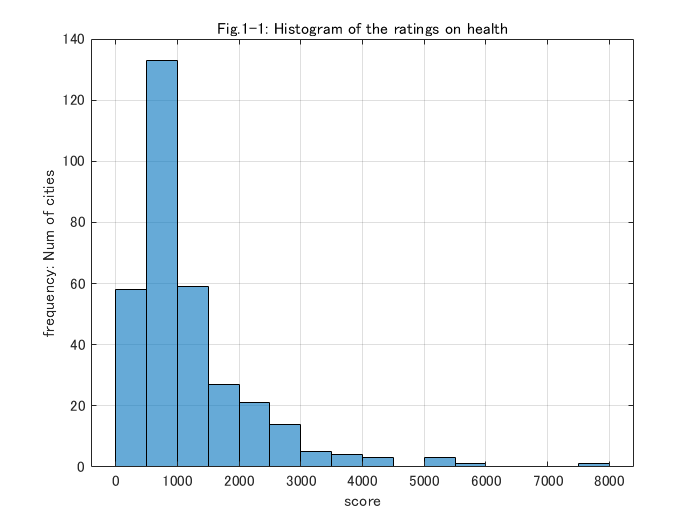

figure('Name','Fig.1-3: Matrix of scatter plots on 3 variables'); % creates a new fingure window

plotmatrix(ratings(:,[3 6 7])); % plots a scatter plot for every combination of three varialbes, health (3rd column), education (6th), and arts (7th), and histograms for three varialbes

３つの変数のうち２つずつのペアごとに散布図を示しています．各行は上から「健康」「教育」「芸術」に対応します．各列は左から「健康」「教育」「芸術」に対応します．たとえば，１行２列目の散布図は横軸に「健康」，縦軸に「教育」の満足度指標をプロットしています．対角線上のヒストグラムは左上から「健康」「教育」「芸術」の満足度指標のヒストグラムです．対角線上より左下のヒストグラムは，右上のヒストグラムと縦軸と横軸が入れ替わったものです．たとえば，２行１列目は横軸が「教育」，縦軸が「健康」になります．対角線より右上の散布図をみると，どの変数同士の組み合わせにおいても，正の相関があるように見えます．なかでも「健康」と「芸術」の満足度指標の間には比較的強い相関がありそうです．このように，変数がえつ程度であれば，変数を２つずつ組み合わせて散布図を作成することである程度の関係性を調べることができます．しかし，この方法で見られるのは，飽くまでも２つの変数ごとの関係性です．３つ以上の複雑な関係性を見ることはできません．もし，３つの変数の関係を一度に見ようとすれば三次元の散布図を作成することになります．実際に見てみましょう．

figure('Name','Fig.1-4: 3D scatter plot on health, education, and economics'); % creates a new figure window

ratings_health_edu =          237        2757
        1656        2438
         618        2560
        1431        3399
        1853        3026
         640        2972
         621        3144
         965        2945
         432        2778
         669        2852


scatter3(ratings(:,3),ratings(:,6),ratings(:,7)); grid on; % plots a 3D scatter plot on the three variables
title('Fig.1-4: 3D scatter plot on health, education, and economics'); % adds title
xlabel('health'); ylabel('education'); zlabel('arts'); % adds labels to x-, y-, and z-axis
set(gca,'Xscale','log','Yscale','log','Zscale','log'); % sets axes to log scale 
axis([0 60000 0 60000 0 60000]); % specifies the limits of axes to range from 0 to 60000

この図を回転させて眺めることで，様々な角度から変数の関係を眺めることが出来ます．先ほど確認したことと同様に，「健康」と「芸術」の満足度指標の間の相関がもっとも強いことがわかります．

#### ９変数

それでは，変数が４つ以上の場合はどうすればよいでしょうか．９つの指標すべてを含む場合を考えてみます．変数ペアごとに散布図を作成してみましょう．

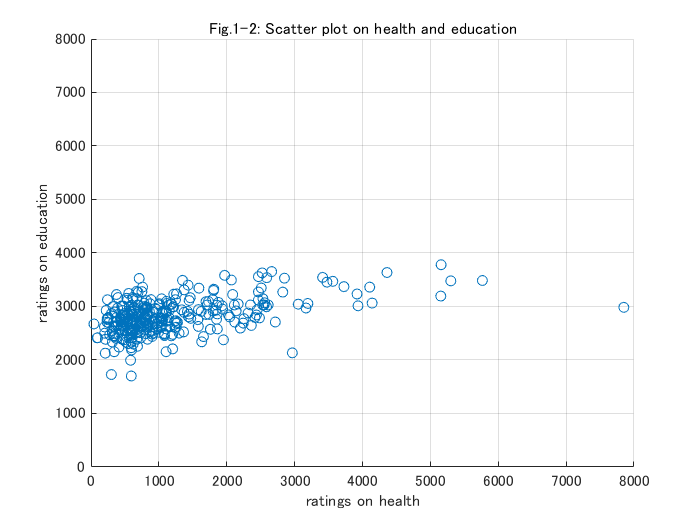

figure('Name','Fig.1-5: Matrix of scatter plots on 9 variables'); % creates a new figure window

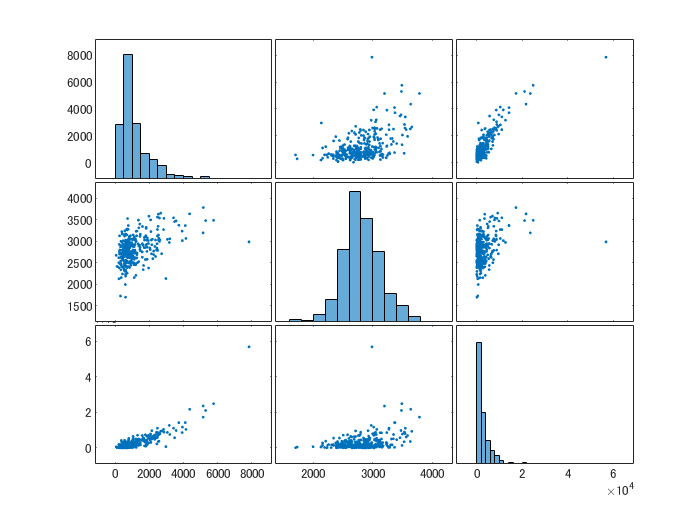

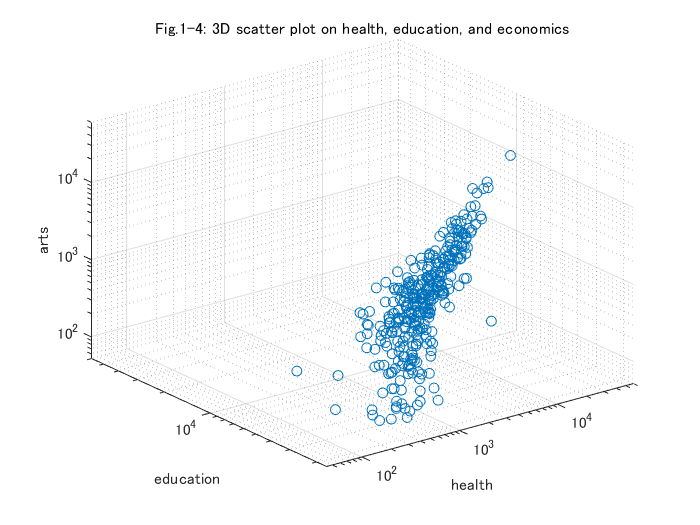

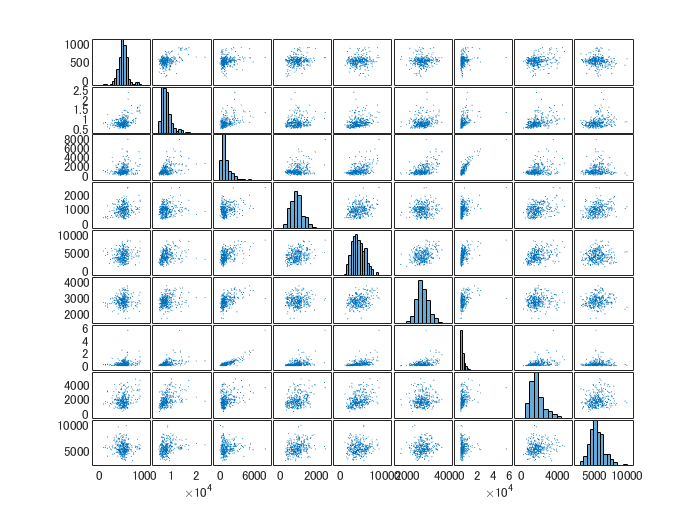

plotmatrix(ratings); % plots scatter plots for all pairs of the variables and histograms for all variables.

変数の数が増えたことで，ひとつひとつのグラフが小さくなりましたが，注意深く観察すると，いくつかの関係を読み取ることができます．対角線より右上の散布図に着目すると，３行７列目の散布図がもっとも強い相関を示しているように見えます．また，２行目から４行目（「住宅」「健康」「犯罪」）まではどの変数とも大なり小なりの相関があるように見えます．一方，１行目の「気候」はどの変数ともあまり関係していないように見えます．

#### 変数が増えることの難しさ

変数の数が９つの場合でも，変数ペアごとの散布図をみると変数間の関係を視覚的に確認することができました．また，それぞれの変数について要約統計量を計算したり，変数ペアごとに相関係数を計算したりすることも出来ます．しかし，変数の数がさらに増えて数百や数千の変数をもつ多変量データになるとこのようなやり方が通用しなくなることは想像に難くありません．データの要約統計量を計算したりやデータをグラフにしたりすることは，データの傾向を把握するためにとても強力かつ簡単な方法です．一変量データや二変量データなど，変数が比較的少ない場合は，それだけで十分にデータの傾向を把握することができます．しかし，変数の数が増えてくると，データの全体像を把握するために計算すべき要約統計量や作成すべきグラフの数が増えてしまいます．数百の変数をもつデータの場合，変数の数だけ要約統計量を計算する必要があります．また，二変数間の相関係数を求めたり散布図を作成する場合は，組み合わせの数はさらに膨大になります．データの全体的な傾向を把握するための要約統計量もグラフも，数が増えれば人間の認知能力を上回ってしまって，そのデータの意味や背後にある法則を捉えることが難しくなります．さらに，多変量データには３つ以上の変数におよぶ関係性が潜んでいる可能性もあります．そのような関係性を変数ペアごとの相関を調べるだけで認識することは難しくなります．変数の数が数百とか数千といったデータを手にした場合，それらを定量的に扱う手法が多変量解析です．